# 1 DOF Cell Model in plane strain

## Data

clear all; close all; clc;
set_env;
addpath("Functions and Scripts\");
addpath("1DOF\");
load("cell_1dof_pstrain.mat")

% Data
eps1_max = 0.05;
% Symbolic variables ------------------------------------------------
% Geometry of the capacitor
syms x l_0 tf_0 dtf xi xi_0
syms epsilon_1(x) sigma_1(x) sigma_2(x) epsilon1_max

% syms epsilon_1(x) epsilon_2(x) epsilon_3(x) sigma_1(x)
% makeassumptions

## Equations

% Geometry ------------------------------
dt_f(x) = simplify(solve((x/2 - tf_0 / 2) / l_0 == (dtf / 2) / (l_0 - (xi - xi_0)), dtf), 25)

$$dt\_f(x) = -\frac{\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-\xi +\xi_{0}\right)}{l_{0}}$$

t_f(x) = tf_0 + dt_f;


w = pstrain_1dof.w

$$w = w_{0}$$

t_p = pstrain_1dof.t_p

$$t\_p = {\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)$$

l = pstrain_1dof.l

$$l = l_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)$$

A = pstrain_1dof.A

$$A = l_{0}\,w_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)$$

C_str = pstrain_1dof.C

$$C\_str(x) = \left\{ \begin{array}{cl} \frac{\epsilon_{f}\,\epsilon_{p}\,l_{0}\,w_{0}}{\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}} & \text{ if }x\leq {\mathrm{tf}}_{0}+\frac{1}{10000000000}\\ \frac{\epsilon_{f}\,l_{0}\,w_{0}\,\log\left(-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tf}}_{0}-x}-\frac{\epsilon_{f}\,l_{0}\,w_{0}\,\log\left(\epsilon_{p}\,l_{0}\,\left({\mathrm{tf}}_{0}-x\right)-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tf}}_{0}-x} & \text{ if }{\mathrm{tf}}_{0}+\frac{1}{10000000000}<x \end{array}\right.$$

Vol = pstrain_1dof.Vol

$$Vol = l_{0}\,{\mathrm{tp}}_{0}\,w_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)\,\left(\epsilon_{3}\left(x\right)+1\right)$$

Vol_0 = pstrain_1dof.Vol_0

$$Vol\_0 = l_{0}\,{\mathrm{tp}}_{0}\,w_{0}$$


pstrain = sstrain1(pstrain_1dof, "PSTRAIN");
C = pstrain.C;
Vmax = pstrain.Vmax;
Uel = pstrain.Uel;
F = pstrain.F;
FVmax = pstrain.FVmax;
FVmin = pstrain.FVmin;

% Range limit
x_min = vpa(sdata1(pstrain.x_min), 4)

$$x\_min = 0.0001$$

x_max = subs(sstrain1(pstrain.x_max), epsilon1_max, eps1_max);
x_max = vpa(sdata1(rhs(isolate(x_max, x))), 4)

$$x\_max = 0.01611$$

x_minmax = [double(x_min) double(x_max)];


## Capacitance

% Min capacitance
Cmin = vpa(subs(sdata1(C), x, x_max), 4)

$$Cmin(x) = 1.864e-11$$


% Max C
Cmax = vpa(subs(sdata1(C), x, sdata1(tf_0)), 4)

$$Cmax(x) = 4.276e-10$$

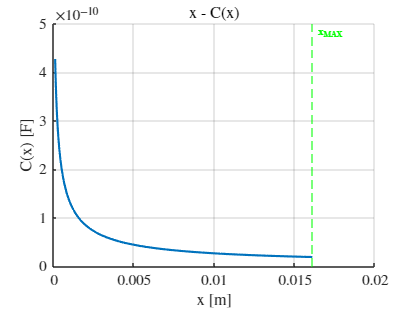

% Plot x - C(x)
myfig(1,"x - C(x)");
hold on; 
fplot(x, sdata1(C(x)), x_minmax, 'LineWidth', 2)
myxline(double(sdata1(x_max)), "x_{MAX}")
hold off
title("x - C(x)")
xlabel("x [m]")
ylabel("C(x) [F]")

## Max voltage

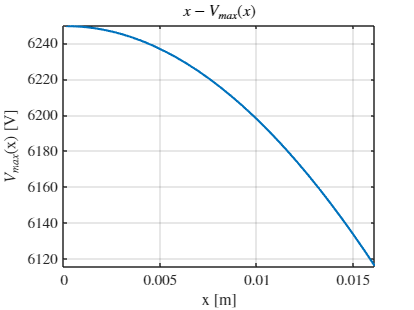

% Max voltage
% Vmax(x) = A / C * min(epsilon_p * EBD_p, epsilon_f * EBD_f)

% Plot x - Vmax(x)
myfig(2,"x - Vmax(x)");
fplot(x, sdata1(Vmax(x)), x_minmax, 'LineWidth', 2)
title("$x - V_{max}(x)$")
xlabel("x [m]")
ylabel("$V_{max}$(x) [V]")

## Force

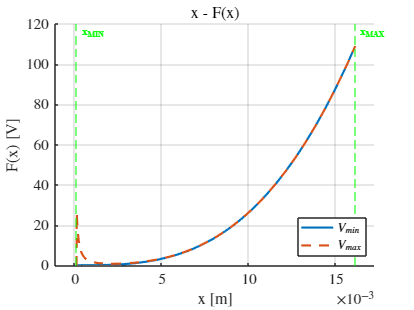

% Plot x - F(x) 
myfig(3,"x - F(x)"); hold on
fplot(x, sdata1(FVmin), x_minmax, 'LineWidth', 2, 'DisplayName', '$V_{min}$')
fplot(x, sdata1(real(FVmax)), x_minmax, '--', 'LineWidth', 2, 'DisplayName', '$V_{max}$')
myxline(x_minmax(1), "x_{MIN}")
myxline(x_minmax(2), "x_{MAX}")
title("x - F(x)")
legend("Location","southeast")
xlabel("x [m]")
ylabel("F(x) [V]")
xlim("padded")

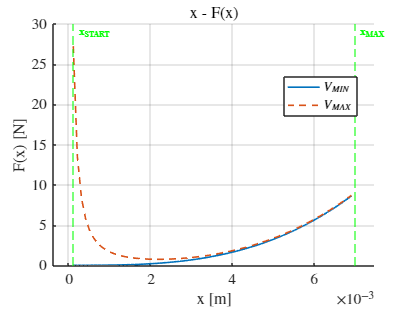

% Redefine x limits
x_range = double(x_min:1e-5:x_max);
FVmax_vec = double(subs(sdata1(FVmax),x_range));
FVmin_vec = double(subs(sdata1(FVmin),x_range));
[fvmax_peak, idx] = findpeaks(FVmax_vec);
x_start = x_range(idx);
x_end = double(min(sdata1(x_max), 7e-3));
x_startend = double(x_start:1e-4:x_end);

FVmax_vec = double(subs(sdata1(FVmax), x_startend));
FVmin_vec = double(subs(sdata1(FVmin), x_startend));

myfig(4,"x - F(x)")
hold on
plot(x_startend, FVmin_vec, 'LineWidth', 1.5, 'DisplayName', "$V_{MIN}$")
plot(x_startend, real(FVmax_vec),'--', 'LineWidth', 1.5, 'DisplayName', "$V_{MAX}$")
myxline(x_start, "x_{START}")
myxline(x_end, "x_{MAX}")
hold off
legend("Location", "best")
title("x - F(x)")
xlim("padded")
xlabel("x [m]")
ylabel("F(x) [N]")

% Energy from x - F(x)
Uel_Fx = double(trapz(x_startend, FVmax_vec) - trapz(x_startend, FVmin_vec))

Uel_Fx = 0.0076

## Q - V

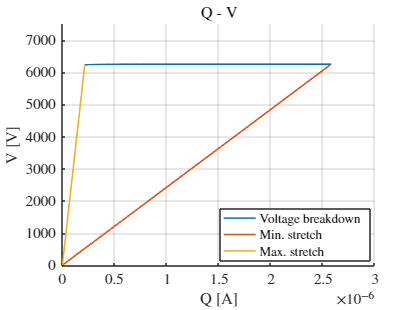

% Plot Q - V
C_vec = double(subs(sdata1(C), x, x_startend));
Vmax_vec = double(subs(sdata1(Vmax), x, x_startend));
Q_vec = C_vec .* Vmax_vec;
C_min_val = C_vec(end);
C_max_val = C_vec(1);
V_vec = linspace(0, min(Vmax_vec), 100);
Qmaxstr = double(V_vec * C_min_val);
Qminstr = double(V_vec * C_max_val);

myfig(5,"Q - V");
hold on
plot(Q_vec, Vmax_vec, 'DisplayName', "Voltage breakdown", "LineWidth", 1.5)
plot(Qminstr, V_vec, 'DisplayName', "Min. stretch", "LineWidth", 1.5)
plot(Qmaxstr, V_vec, 'DisplayName', "Max. stretch", "LineWidth", 1.5)
legend('Location','best')
xlabel("Q [A]")
ylabel("V [V]")
ylim([0, 1.2 * max(Vmax_vec)])
title("Q - V")
hold off

% Energy from Q - V
Uel_QV = trapz(Qmaxstr, V_vec) + trapz(sort(Q_vec,'ascend'), Vmax_vec) - trapz(Qminstr, V_vec)

Uel_QV = 0.0074

% Save results
Uel_vec = double(subs(sdata1(Uel), x, x_startend));

Uel_vec =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0009    0.0010    0.0012    0.0013    0.0014    0.0016    0.0018    0.0020    0.0022    0.0024    0.0026    0.0028    0.0031    0.0034    0.0037    0.0040



res_1dof_pstrain.x_startend = x_startend;
res_1dof_pstrain.C_vec = C_vec;
res_1dof_pstrain.Vmax_vec = Vmax_vec;
res_1dof_pstrain.Uel_vec = Uel_vec;
res_1dof_pstrain.FVmin_vec = FVmin_vec;
res_1dof_pstrain.FVmax_vec = FVmax_vec;
res_1dof_pstrain.Uel_Fx = Uel_Fx;
res_1dof_pstrain.Uel_QV = Uel_QV;
res_1dof_pstrain.Cmin = C_vec(end);
res_1dof_pstrain.Cmax = C_vec(1);
res_1dof_pstrain.Q_vec = Q_vec;
res_1dof_pstrain.V_vec = V_vec;
res_1dof_pstrain.Qmaxstr = Qmaxstr;
res_1dof_pstrain.Qminstr = Qminstr;

save("1DOF\res_1dof_pstrain.mat", "res_1dof_pstrain")



